# Create Deep Learning Network Architecture

Script for creating the layers for a deep learning network with:

Run the script to create the layers in the workspace variable `lgraph`.

To learn more, see [Generate MATLAB Code From Deep Network Designer](matlab:helpview('deeplearning','generate_matlab_code')).

Auto-generated by MATLAB on 28-Feb-2020 16:16:58

## Create the Layer Graph

Create the layer graph variable to contain the network's layers.

lgraph = layerGraph();

## Add the Layer Branches

Add the branches of the network to the layer graph. Each branch is a linear array of layers.

tempLayers = [
    imageInputLayer([32 32 3],"Name","imageinput")
    batchNormalizationLayer("Name","batchnorm_1")
    convolution2dLayer([3 3],8,"Name","conv_1","Padding","same")
    leakyReluLayer(0.01,"Name","leakyrelu_1")
    convolution2dLayer([1 1],8,"Name","conv_2")
    leakyReluLayer(0.01,"Name","leakyrelu_2")
    convolution2dLayer([3 3],32,"Name","conv_3","Padding",[1 1 1 1])
    batchNormalizationLayer("Name","batchnorm_2")
    reluLayer("Name","relu_1")
    maxPooling2dLayer([2 2],"Name","maxpool_1","Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],64,"Name","conv_4","Padding",[1 1 1 1])
    batchNormalizationLayer("Name","batchnorm_3")
    reluLayer("Name","relu_2")
    maxPooling2dLayer([2 2],"Name","maxpool_2","Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = convolution2dLayer([3 3],64,"Name","conv_8","Padding",[1 1 1 1],"Stride",[2 2]);
lgraph = addLayers(lgraph,tempLayers);

tempLayers = additionLayer(2,"Name","addition_1");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = convolution2dLayer([3 3],96,"Name","conv_9","Padding",[1 1 1 1],"Stride",[2 2]);
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],96,"Name","conv_5","Padding",[1 1 1 1])
    batchNormalizationLayer("Name","batchnorm_4")
    reluLayer("Name","relu_3")
    dropoutLayer(0.1,"Name","dropout_1")
    maxPooling2dLayer([2 2],"Name","maxpool_3","Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = additionLayer(2,"Name","addition_2");
lgraph = addLayers(lgraph,tempLayers);

tempLayers = convolution2dLayer([3 3],43,"Name","conv_10","Padding",[1 1 1 1],"Stride",[4 4]);
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    convolution2dLayer([3 3],128,"Name","conv_6","Padding",[1 1 1 1])
    batchNormalizationLayer("Name","batchnorm_5")
    reluLayer("Name","relu_4")
    convolution2dLayer([3 3],43,"Name","conv_7","Padding",[1 1 1 1])
    batchNormalizationLayer("Name","batchnorm_6")
    reluLayer("Name","relu_5")
    dropoutLayer(0.1,"Name","dropout_2")
    maxPooling2dLayer([4 4],"Name","maxpool_4","Stride",[2 2])];
lgraph = addLayers(lgraph,tempLayers);

tempLayers = [
    additionLayer(2,"Name","addition_3")
    fullyConnectedLayer(43,"Name","fc")
    softmaxLayer("Name","softmax")
    classificationLayer("Name","classoutput")];
lgraph = addLayers(lgraph,tempLayers);

## Connect the Layer Branches

Connect all the branches of the network to create the network's graph.

lgraph = connectLayers(lgraph,"maxpool_1","conv_4");
lgraph = connectLayers(lgraph,"maxpool_1","conv_8");
lgraph = connectLayers(lgraph,"conv_8","addition_1/in2");
lgraph = connectLayers(lgraph,"maxpool_2","addition_1/in1");
lgraph = connectLayers(lgraph,"addition_1","conv_9");
lgraph = connectLayers(lgraph,"addition_1","conv_5");
lgraph = connectLayers(lgraph,"conv_9","addition_2/in2");
lgraph = connectLayers(lgraph,"maxpool_3","addition_2/in1");
lgraph = connectLayers(lgraph,"addition_2","conv_10");
lgraph = connectLayers(lgraph,"addition_2","conv_6");
lgraph = connectLayers(lgraph,"conv_10","addition_3/in2");
lgraph = connectLayers(lgraph,"maxpool_4","addition_3/in1");

## Clean Up Helper Variable

clear tempLayers;

## Plot the Layers

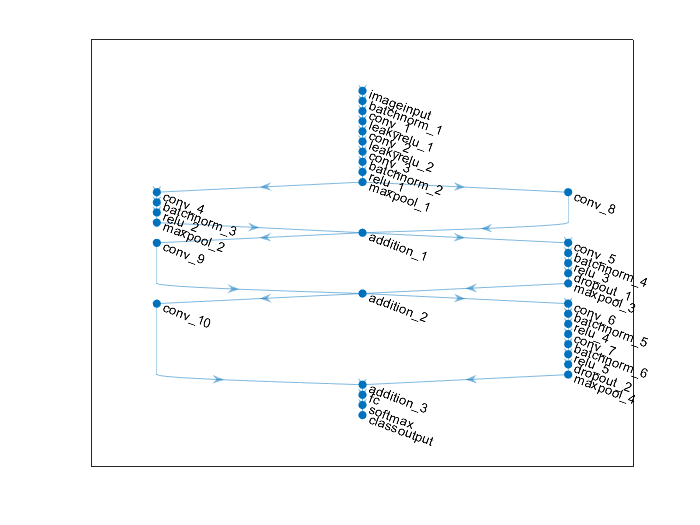

plot(lgraph);